clear all
close all
clc

data = readtable("results\all_data.csv");

% figure
% boxplot([data.param_0_,data.param_1_,data.param_2_,data.param_3_])

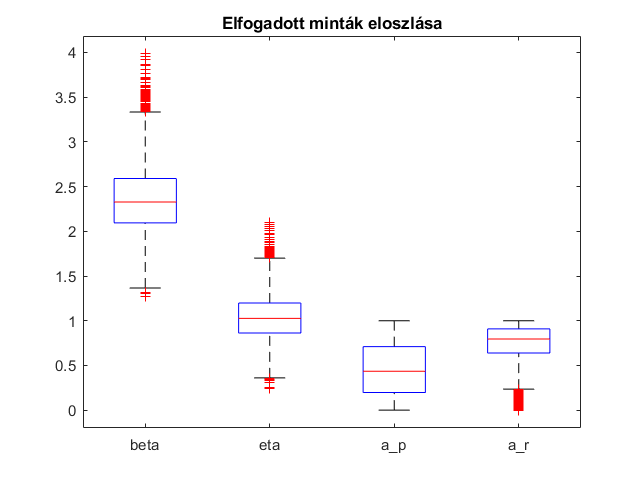

accepted = data(data.accepted == 1,:);
figure
boxplot([accepted.param_0_,accepted.param_1_,accepted.param_2_,accepted.param_3_],["beta" "eta" "a_p" "a_r"])
title("Elfogadott minták eloszlása")

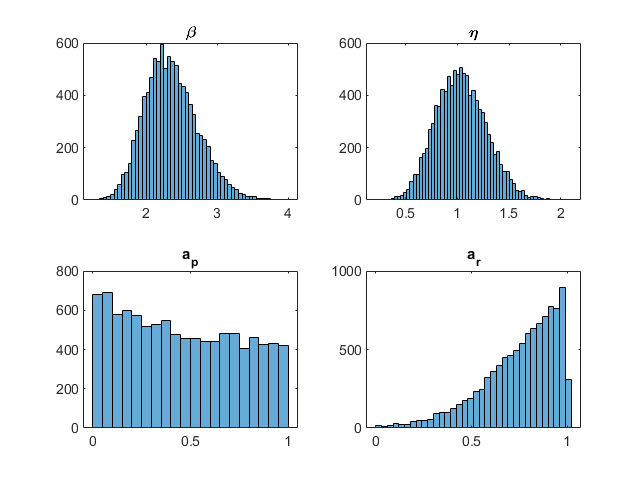

figure
title("Elfogadott minták hisztogrammja")
subplot(2,2,1)
histogram(accepted.param_0_)
title("\beta")
subplot(2,2,2)
histogram(accepted.param_1_)
title("\eta")
subplot(2,2,3)
histogram(accepted.param_2_)
title("a_{p}")
subplot(2,2,4)
histogram(accepted.param_3_)
title("a_{r}")

%results
beta_ = mean(accepted.param_0_)

beta_ = 2.3566

eta_ = mean(accepted.param_1_)

eta_ = 1.0362

a_r_ = mean(accepted.param_2_)

a_r_ = 0.4590

a_p_ = mean(accepted.param_3_)

a_p_ = 0.7523

beta_sigm = sqrt(var(accepted.param_0_))

beta_sigm = 0.3731

eta_sigm = sqrt(var(accepted.param_1_))

eta_sigm = 0.2448

a_r_sigm = sqrt(var(accepted.param_2_))

a_r_sigm = 0.2931

a_p_sigm = sqrt(var(accepted.param_3_))

a_p_sigm = 0.1950

%result %
b = beta_ / 2.339*100

b = 100.7512

e = eta_ / 1.031*100

e = 100.5044

r = a_r_ /0.468*100

r = 98.0848

p = a_p_ / 0.745*100

p = 100.9753

100-mean([b r e p])

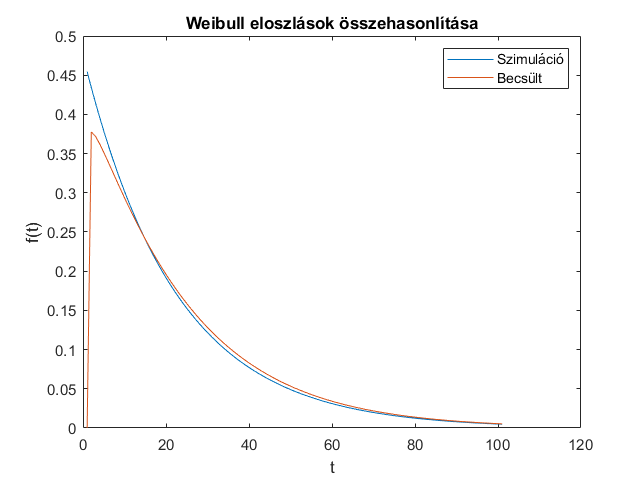

%Distribution guess comparsion
figure
x = 0:0.1:10;
original_pdf = wblpdf(x,2.2,1);
plot(original_pdf)
hold  on
plot(wblpdf(x,beta_,eta_))
title("Weibull eloszlások összehasonlítása")
xlabel t
ylabel f(t)
legend(["Szimuláció " "Becsült "])